clear
clc

## Univariate Gaussian

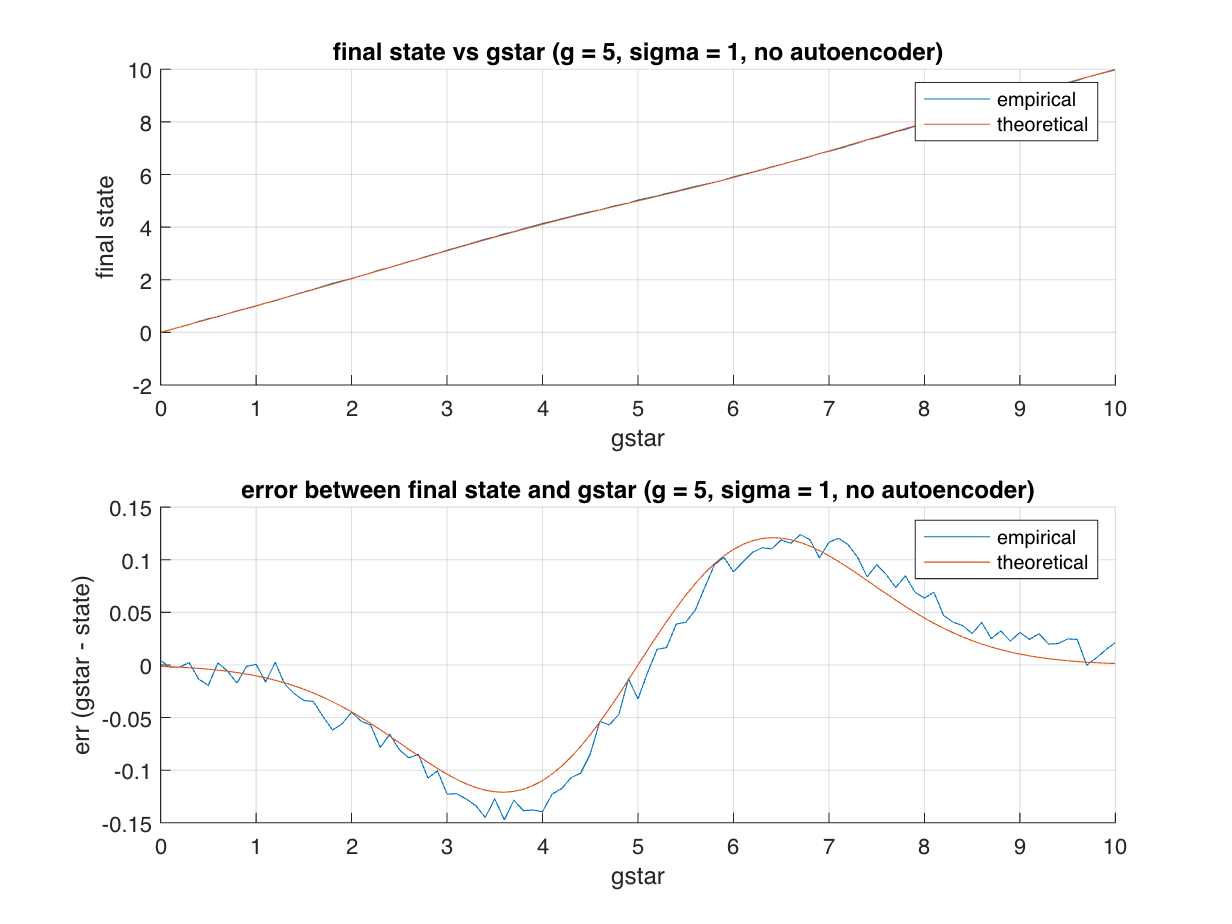

n_steps = 100000;
g = 5;
sigma_h = 1;
sigma_d = 1;
s = 0;
g_breadth = 10;
emps_s = zeros(1,g_breadth * 10);
cals_s = zeros(1,g_breadth * 10);
pos = 1;
for gstar = 0:0.1:g_breadth
    a_h = normrnd((gstar-s),sigma_h, [1,n_steps]);
    a_r = normrnd((g-s),sigma_d, [1,n_steps]);
    alpha =  normpdf(a_h,(g-s),sigma_d);
    exp_ar = g - s;
    exp_ah = gstar - s;
    exp_alpha = 1/sqrt(2*pi*(sigma_d^2+sigma_h^2)) * exp(-1/2*(gstar - g)^2/(sigma_d^2+sigma_h^2));
    exp_alpha_ah = ((gstar-s)*sigma_d^2 + (g-s)*sigma_h^2)/(sqrt(2*pi)*(sigma_d^2+sigma_h^2)^(3/2)) * exp(-1/2*(gstar - g)^2/(sigma_d^2+sigma_h^2));
    a = exp_ah - exp_alpha_ah + exp_alpha*exp_ar;
    sdot = ((1-alpha).*a_h + alpha.*a_r);
    emps_s(pos) = mean(sdot);
    cals_s(pos) = a;
    pos = pos + 1;
end
figure
gstar = 0:0.1:g_breadth;
final_state_novae = [-0.004227039462959684, 0.10225930766994579, 0.20193273607772952, 0.2977561030553869, 0.41362606793341783, 0.5192687484882316, 0.5980837815700681, 0.7057006922870176, 0.817254951178181, 0.901351278100892, 0.9993782395408587, 1.1162677554986848, 1.1975735502357945, 1.3181835839613587, 1.4271881568854712, 1.5338406436020595, 1.6347254244608564, 1.7488302581275743, 1.861905150087225, 1.9560166862187882, 2.044889633957601, 2.1534182377053552, 2.2571132380110246, 2.378437438140184, 2.465836948705849, 2.580519036786462, 2.6882996856329315, 2.784979787474781, 2.907495061381262, 3.000623435554726, 3.1226546828929203, 3.222376943388615, 3.327411360888627, 3.43350001586045, 3.5449747043609947, 3.627225339626694, 3.7472282328883324, 3.8285613589227907, 3.9384925811231892, 4.037838969062957, 4.139486693201666, 4.222800383636186, 4.317525949529553, 4.40705708217709, 4.502836019592454, 4.584643511340174, 4.6537185475852745, 4.756929346521414, 4.846958723873689, 4.91317871115595, 5.032387351332567, 5.107292907394477, 5.185227542300194, 5.283455218279384, 5.361153583281958, 5.459360535932469, 5.547914514899978, 5.626115169429893, 5.704932709588974, 5.797696393950524, 5.9115467608640335, 6.002004512560294, 6.093026121257772, 6.188610400746854, 6.289699070167404, 6.381210548772333, 6.484369864465898, 6.576228941330642, 6.680808704129752, 6.798142341648985, 6.883423244110799, 6.979550409536484, 7.08567887647475, 7.197656454160862, 7.316336176251655, 7.4046802740379425, 7.514142526707987, 7.6264790291050435, 7.715311431640033, 7.830741775407418, 7.936488987288487, 8.03089356310063, 8.152892826497666, 8.259365287217177, 8.362537901653655, 8.47015959696663, 8.559552385511953, 8.675029151716059, 8.7676536042508, 8.877365640929117, 8.969119901036462, 9.075710330760373, 9.170294832411304, 9.280199601376019, 9.379686547309426, 9.475246014914248, 9.57576068171486, 9.700206003414511, 9.793311336175883, 9.885474092581262, 9.978782907111322];
err_novae = [0.004227039462959684, -0.0022593076699457815, -0.0019327360777295077, 0.002243896944613133, -0.013626067933417807, -0.01926874848823157, 0.0019162184299319485, -0.005700692287017528, -0.01725495117818099, -0.0013512781008919728, 0.0006217604591413073, -0.016267755498684755, 0.002426449764205696, -0.018183583961358663, -0.02718815688547105, -0.03384064360205952, -0.03472542446085636, -0.04883025812757413, -0.06190515008722497, -0.05601668621878808, -0.04488963395760104, -0.05341823770535514, -0.057113238011024414, -0.07843743814018378, -0.06583694870584855, -0.0805190367864621, -0.08829968563293145, -0.08497978747478063, -0.10749506138126153, -0.10062343555472575, -0.12265468289292025, -0.12237694338861482, -0.12741136088862692, -0.13350001586044957, -0.14497470436099436, -0.12722533962669402, -0.1472282328883323, -0.12856135892279053, -0.13849258112318896, -0.13783896906295645, -0.13948669320166562, -0.12280038363618573, -0.11752594952955242, -0.1070570821770902, -0.10283601959245381, -0.08464351134017356, -0.053718547585273946, -0.05692934652141357, -0.04695872387368816, -0.01317871115595004, -0.03238735133256743, -0.007292907394476522, 0.014772457699805841, 0.016544781720616797, 0.038846416718042676, 0.04063946406753072, 0.05208548510002231, 0.07388483057010742, 0.09506729041102702, 0.10230360604947641, 0.08845323913596648, 0.09799548743970643, 0.1069738787422283, 0.11138959925314662, 0.11030092983259632, 0.11878945122766726, 0.11563013553410251, 0.12377105866935789, 0.11919129587024901, 0.10185765835101535, 0.11657675588920124, 0.12044959046351611, 0.11432112352524992, 0.10234354583913863, 0.08366382374834558, 0.09531972596205751, 0.08585747329201343, 0.07352097089495668, 0.08468856835996785, 0.06925822459258235, 0.06351101271151283, 0.06910643689936968, 0.04710717350233473, 0.04063471278282371, 0.03746209834634584, 0.029840403033370322, 0.04044761448804657, 0.02497084828394236, 0.03234639574920095, 0.022634359070883292, 0.030880098963537606, 0.024289669239626832, 0.029705167588696568, 0.019800398623981863, 0.020313452690574607, 0.024753985085752106, 0.02423931828514192, -0.00020600341450993653, 0.006688663824117924, 0.01452590741873827, 0.021217092888678124];
subplot(2,1,1)
hold on
grid on
plot(gstar, final_state_novae)
plot(gstar, cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('final state')
title('final state vs gstar (g = 5, sigma = 1, no autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(gstar, err_novae)
plot(gstar, gstar - cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('err (gstar - state)')
title('error between final state and gstar (g = 5, sigma = 1, no autoencoder)')

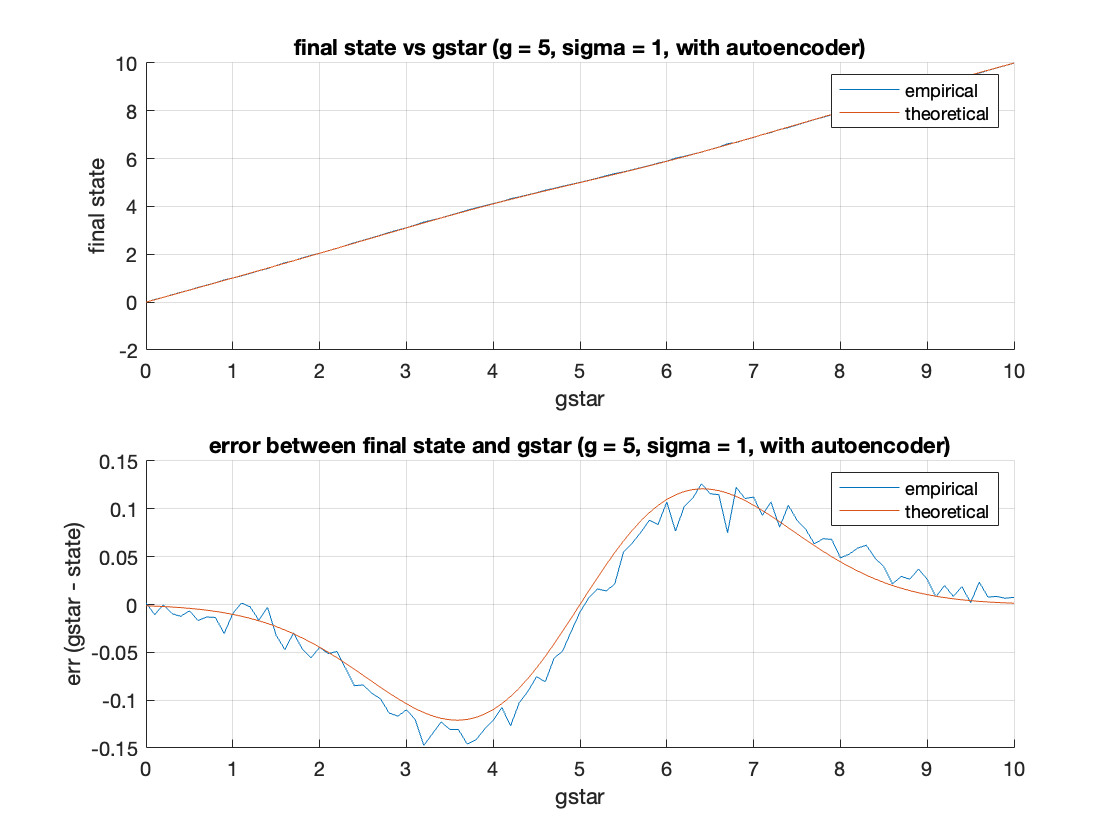

%vae
final_state_vae = [-0.0019034813, 0.11068548, 0.20017153, 0.3095327, 0.4123922, 0.50660485, 0.616696, 0.71307546, 0.8135207, 0.93041795, 1.0094376, 1.0984528, 1.2023937, 1.3165864, 1.4030305, 1.5322664, 1.6471889, 1.7294472, 1.8466812, 1.9558094, 2.0447803, 2.1513584, 2.249059, 2.3667657, 2.484868, 2.5841017, 2.692586, 2.7984722, 2.9132748, 3.0167792, 3.1101563, 3.2199683, 3.3472977, 3.4350984, 3.52279, 3.6305516, 3.7307758, 3.84576, 3.941609, 4.03036, 4.121172, 4.2076735, 4.326828, 4.402743, 4.4907904, 4.5754066, 4.680847, 4.7563086, 4.848498, 4.927904, 5.00789, 5.093196, 5.1836576, 5.2858415, 5.3786626, 5.4454346, 5.535992, 5.6247005, 5.71185, 5.8162737, 5.892778, 6.023297, 6.097906, 6.1888146, 6.2737594, 6.3841796, 6.485288, 6.6250844, 6.677487, 6.7891936, 6.887692, 7.006911, 7.0927196, 7.2192736, 7.2962193, 7.4118404, 7.521455, 7.636439, 7.7313256, 7.8319283, 7.9513154, 8.047384, 8.141002, 8.238068, 8.351617, 8.460493, 8.57858, 8.670619, 8.773563, 8.863011, 8.973609, 9.091993, 9.180086, 9.291536, 9.381337, 9.498098, 9.57654, 9.692243, 9.791559, 9.893452, 9.992575];
err_vae =  [0.0019034813158214092, -0.010685482621192927, -0.00017153024673460804, -0.009532701969146684, -0.012392199039459206, -0.0066048502922058105, -0.01669600009918204, -0.01307545900344842, -0.01352072954177852, -0.03041795492172239, -0.00943756103515625, 0.0015471935272217685, -0.0023936510086057794, -0.016586375236511186, -0.0030305147171019176, -0.03226637840270996, -0.04718890190124503, -0.029447245597839178, -0.046681237220764116, -0.05580935478210436, -0.04478025436401367, -0.05135836601257315, -0.049058961868285955, -0.06676573753356907, -0.08486804962158168, -0.08410167694091797, -0.09258594512939444, -0.09847216606140119, -0.11327476501464817, -0.11677918434143031, -0.11015629768371582, -0.1199683189392089, -0.14729766845703107, -0.1350984096527097, -0.1227899551391598, -0.13055157661437988, -0.13077583312988272, -0.1457601070404051, -0.14160890579223606, -0.1303602218627926, -0.12117195129394531, -0.10767354965209908, -0.12682800292968732, -0.1027428627014162, -0.09079036712646449, -0.07540655136108398, -0.08084716796874947, -0.056308555603027166, -0.048497867584227805, -0.027904129028319957, -0.00789022445678711, 0.006804084777832564, 0.01634235382080096, 0.01415853500366282, 0.021337413787842152, 0.0545654296875, 0.06400785446167045, 0.07529945373535174, 0.08814983367919993, 0.08372631072998082, 0.10722208023071289, 0.07670316696167045, 0.10209388732910174, 0.1111853599548347, 0.12624063491821325, 0.11582040786743164, 0.11471185684204155, 0.07491559982299822, 0.12251310348510813, 0.1108063697814945, 0.11230802536010742, 0.09308919906616264, 0.10728044509887713, 0.08072643280029368, 0.10378065109252965, 0.08815956115722656, 0.07854518890380913, 0.06356115341186541, 0.0686743736267097, 0.06807174682617223, 0.04868459701538086, 0.05261573791503871, 0.0589982986450206, 0.06193237304687571, 0.0483831405639652, 0.03950691223144531, 0.021420097351073863, 0.029380989074708097, 0.026436614990235086, 0.036988639831543324, 0.026391029357910156, 0.008006668090819957, 0.019913864135743253, 0.008463668823242898, 0.018662834167480824, 0.0019016265869140625, 0.02346000671386861, 0.0077573776245127846, 0.008440780639649148, 0.00654830932617223, 0.0074253082275390625];
figure
subplot(2,1,1)
hold on
grid on
plot(gstar, final_state_vae)
plot(gstar, cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('final state')
title('final state vs gstar (g = 5, sigma = 1, with autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(gstar, err_vae)
plot(gstar, gstar - cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('err (gstar - state)')
title('error between final state and gstar (g = 5, sigma = 1, with autoencoder)')

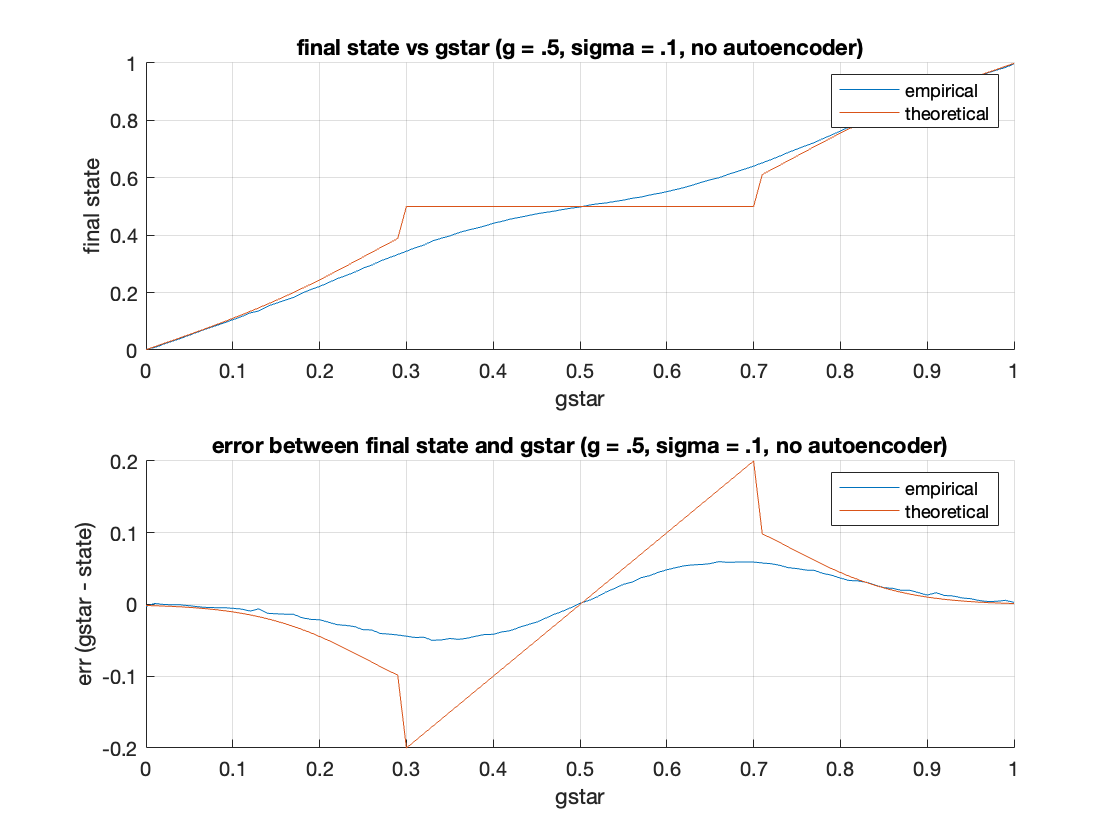

n_steps = 100000;
g = 0.5;
sigma_h = 0.1;
sigma_d = 0.1;
s = 0;
g_breadth = 1;
emps_s = zeros(1,g_breadth * 10);
cals_s = zeros(1,g_breadth * 10);
pos = 1;
max_alpha = 1;
for gstar = 0:0.01:g_breadth
    a_h = normrnd((gstar-s),sigma_h, [1,n_steps]);
    a_r = normrnd((g-s),sigma_d, [1,n_steps]);
    alpha =  normpdf(a_h,(g-s),sigma_d);
    exp_ar = g - s;
    exp_ah = gstar - s;
    exp_alpha = 1/sqrt(2*pi*(sigma_d^2+sigma_h^2)) * exp(-1/2*(gstar - g)^2/(sigma_d^2+sigma_h^2));
    exp_alpha_ah = ((gstar-s)*sigma_d^2 + (g-s)*sigma_h^2)/(sqrt(2*pi)*(sigma_d^2+sigma_h^2)^(3/2)) * exp(-1/2*(gstar - g)^2/(sigma_d^2+sigma_h^2));
    if exp_alpha > max_alpha
        exp_alpha = max_alpha;
        exp_alpha_ah = exp_alpha * exp_ah;
    end
    a = exp_ah - exp_alpha_ah + exp_alpha*exp_ar;
    sdot = ((1-alpha).*a_h + alpha.*a_r);
    emps_s(pos) = mean(sdot);
    cals_s(pos) = a;
    pos = pos + 1;
end
figure
gstar = 0:0.01:g_breadth;
final_state_novae = [0.0028345630741159027, 0.00846085454322037, 0.019900109386379986, 0.030419000079264107, 0.04048755848074452, 0.05168865188234493, 0.06306058911361075, 0.07418686333559629, 0.08439514540047871, 0.09452078791667534, 0.10527313761901992, 0.11640217082707872, 0.12919599001472748, 0.13604587319032618, 0.15221711381835235, 0.16297131860589412, 0.17347008280818454, 0.18356797782185508, 0.1985799436039108, 0.2107103363713873, 0.22128685655565078, 0.23453297196913445, 0.24810921573924846, 0.2591065755187437, 0.270706655374725, 0.2850923283056021, 0.29549991016878163, 0.3104185197967091, 0.3213048304532914, 0.33251310983303567, 0.3441744883402073, 0.35593005653361187, 0.3656968275658983, 0.37996948932455754, 0.38932044003838806, 0.39743578511055583, 0.4085507747122381, 0.4170448632778828, 0.4241099242785793, 0.43183647781932877, 0.4415618844640231, 0.44818433079379777, 0.4563933257322494, 0.4618191496939957, 0.4680722320415615, 0.47462254321242997, 0.4791795205715678, 0.4838908942682375, 0.4893488634356445, 0.494154793141792, 0.4982979843517678, 0.5044656894852722, 0.5092694875538984, 0.5124994149068888, 0.517573535888086, 0.5218952166773506, 0.5287660534344337, 0.5327291629008197, 0.5399043196890793, 0.545226699751564, 0.551601129455048, 0.5587704169393543, 0.5660791693283547, 0.5747999120290664, 0.5842193125230843, 0.5929672078907147, 0.6002713566624754, 0.6111705511451806, 0.6209151929430274, 0.6307924629572961, 0.6408056568648165, 0.6521648276717353, 0.66310903061958, 0.6753992619085093, 0.6886675424584844, 0.7000078032502425, 0.7119695532624288, 0.7224999576483242, 0.7367833173578885, 0.749155868060823, 0.7632091650631389, 0.7765350457777064, 0.787012339531489, 0.7990696687139546, 0.8128683293312328, 0.826518977064166, 0.8375359931068324, 0.8500822643737651, 0.8602120552543802, 0.8734698711921121, 0.8868786638401931, 0.8936239540311213, 0.9074353131762734, 0.9181492054280352, 0.9308480998964352, 0.941872881435431, 0.9545231424718772, 0.9658627024793599, 0.9755315413611206, 0.984218118147987, 0.9969713775346405];
err_novae =  [-0.0028345630741159027, 0.0015391454567796302, 9.989061362001422e-05, -0.0004190000792641084, -0.00048755848074451963, -0.0016886518823449256, -0.0030605891136107483, -0.004186863335596286, -0.004395145400478709, -0.004520787916675345, -0.005273137619019916, -0.006402170827078724, -0.009195990014727484, -0.006045873190326179, -0.012217113818352332, -0.012971318605894122, -0.013470082808184541, -0.013567977821855065, -0.018579943603910798, -0.020710336371387306, -0.02128685655565077, -0.024532971969134454, -0.02810921573924846, -0.02910657551874371, -0.030706655374725, -0.035092328305602105, -0.03549991016878162, -0.040418519796709074, -0.041304830453291363, -0.04251310983303569, -0.04417448834020732, -0.045930056533611874, -0.04569682756589827, -0.049969489324557526, -0.049320440038388036, -0.047435785110555795, -0.04855077471223812, -0.04704486327788282, -0.04410992427857929, -0.041836477819328755, -0.04156188446402309, -0.03818433079379774, -0.036393325732249404, -0.031819149693995685, -0.028072232041561507, -0.02462254321242996, -0.0191795205715678, -0.013890894268237475, -0.009348863435644506, -0.0041547931417920125, 0.0017020156482321913, 0.005534310514727858, 0.01073051244610157, 0.017500585093111254, 0.02242646411191407, 0.02810478332264943, 0.03123394656556633, 0.03727083709918033, 0.0400956803109207, 0.044773300248435954, 0.048398870544951955, 0.051229583060645734, 0.053920830671645326, 0.055200087970933565, 0.05578068747691567, 0.05703279210928536, 0.05972864333752459, 0.058829448854819444, 0.05908480705697261, 0.059207537042703984, 0.05919434313518357, 0.05783517232826463, 0.05689096938041993, 0.054600738091490686, 0.05133245754151561, 0.04999219674975752, 0.048030446737571175, 0.04750004235167582, 0.04321668264211154, 0.04084413193917702, 0.036790834936861194, 0.033464954222293675, 0.03298766046851109, 0.030930331286045498, 0.027131670668767205, 0.023481022935833984, 0.022464006893167632, 0.01991773562623489, 0.019787944745619845, 0.016530128807887956, 0.013121336159806929, 0.01637604596887876, 0.01256468682372669, 0.011850794571964807, 0.009151900103564814, 0.008127118564569047, 0.005476857528122769, 0.004137297520640071, 0.004468458638879347, 0.005781881852013004, 0.0030286224653595095];
subplot(2,1,1)
hold on
grid on
plot(gstar, final_state_novae)
plot(gstar, cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('final state')
title('final state vs gstar (g = .5, sigma = .1, no autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(gstar, err_novae)
plot(gstar, gstar - cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('err (gstar - state)')
title('error between final state and gstar (g = .5, sigma = .1, no autoencoder)')

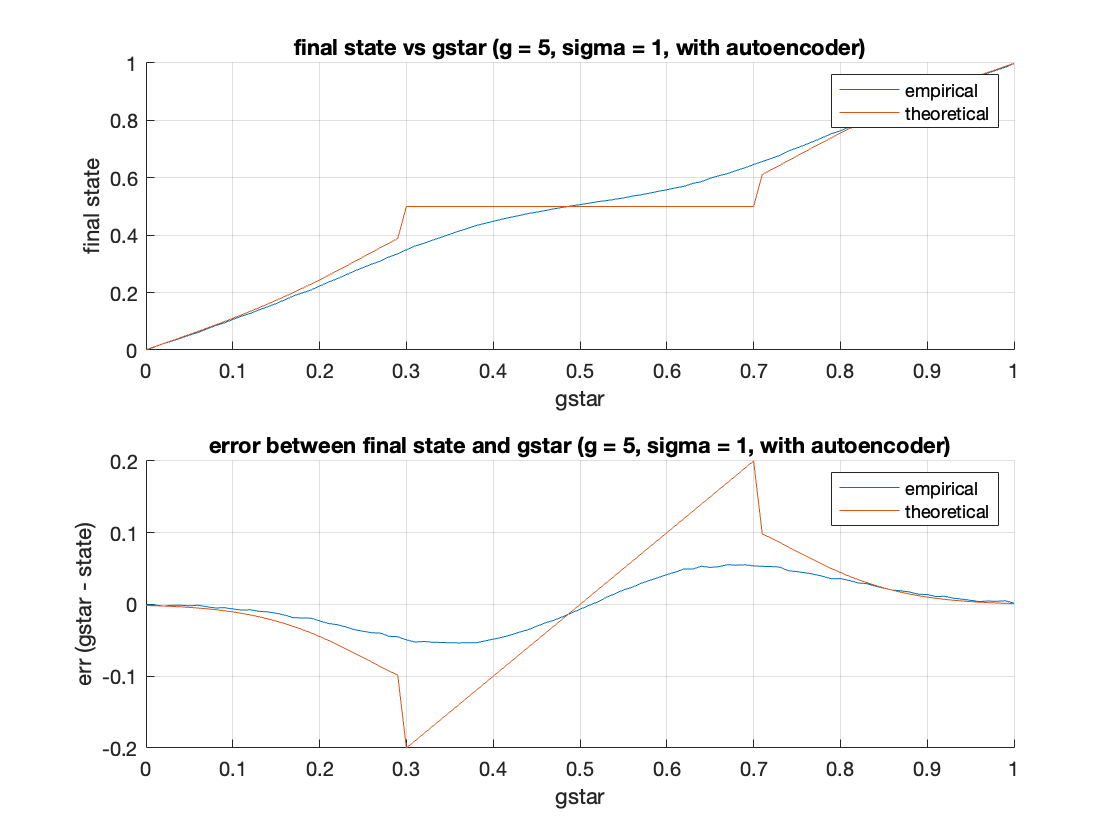

%vae
final_state_vae = [0.00053647015, 0.010588962, 0.022300879, 0.03105947, 0.041006103, 0.05192565, 0.060997333, 0.073200576, 0.08480755, 0.0944837, 0.10618293, 0.11774542, 0.12738505, 0.13952035, 0.15029782, 0.16214114, 0.17483525, 0.18853574, 0.19870749, 0.20906739, 0.22283602, 0.23648076, 0.24800557, 0.26114032, 0.2750339, 0.2872522, 0.29941446, 0.30987, 0.3243096, 0.33490565, 0.349235, 0.36229652, 0.37160122, 0.3825672, 0.39284828, 0.40332696, 0.41352862, 0.4233462, 0.4333709, 0.4408831, 0.4482751, 0.45575762, 0.46247724, 0.46850243, 0.4753728, 0.480319, 0.48560518, 0.49194288, 0.49711987, 0.5018344, 0.506635, 0.5115327, 0.5166589, 0.5201833, 0.5251089, 0.5297031, 0.53607607, 0.5405618, 0.54644305, 0.55253017, 0.5583141, 0.5647935, 0.5705349, 0.58060753, 0.58659494, 0.5983787, 0.60720783, 0.6145791, 0.62516963, 0.63467985, 0.6461712, 0.65679955, 0.66708905, 0.67778087, 0.6929933, 0.70411897, 0.71592075, 0.7280251, 0.7407902, 0.7541123, 0.76390254, 0.77637315, 0.7899047, 0.80085725, 0.81436414, 0.82720137, 0.84003943, 0.85082644, 0.8627032, 0.87564003, 0.8861988, 0.89886975, 0.9085098, 0.92121476, 0.93254256, 0.94415176, 0.95589083, 0.96516365, 0.975516, 0.98483425, 0.9980738];
err_vae = [-0.0005364701501093805, -0.0005889616534113882, -0.002300878539681434, -0.0010594700276851665, -0.0010061031579971305, -0.0019256517291069003, -0.0009973333775997184, -0.0032005760073661738, -0.0048075523972511275, -0.004483703374862674, -0.006182932853698725, -0.0077454218268394465, -0.007385050058364873, -0.009520347118377681, -0.010297820568084703, -0.012141144275665289, -0.014835249781608578, -0.018535735011100757, -0.018707491159439094, -0.019067389369010923, -0.022836017608642567, -0.02648075759410859, -0.028005568981170653, -0.03114031672477721, -0.035033891201019296, -0.037252187728881836, -0.03941445589065551, -0.039870004653930646, -0.04430958747863767, -0.044905654191970845, -0.04923499822616578, -0.052296521663665774, -0.05160122394561767, -0.052567197084426864, -0.052848283052444434, -0.05332695841789242, -0.05352862119674684, -0.053346191644668584, -0.05337088823318481, -0.05088310003280638, -0.04827508926391599, -0.04575761795043942, -0.042477236986160294, -0.03850243210792542, -0.0353727912902832, -0.03031899333000182, -0.025605180263519267, -0.021942882537841768, -0.017119873762130755, -0.01183439254760743, -0.006635010242462158, -0.001532723903655997, 0.003341097831726092, 0.009816675186157253, 0.014891126155853307, 0.020296919345855757, 0.023923931121826225, 0.029438204765319886, 0.033556954860687216, 0.03746983051300046, 0.04168591499328611, 0.04520647287368773, 0.04946511507034301, 0.049392466545104985, 0.053405060768127455, 0.05162128210067751, 0.05279216527938846, 0.055420918464660684, 0.05483036518096929, 0.055320146083831845, 0.05382878780364997, 0.05320044517517086, 0.052910954952239964, 0.05221913337707518, 0.04700671672821044, 0.045881032943725586, 0.044079253673553476, 0.04197492122650148, 0.03920981168746951, 0.03588769674301151, 0.03609745502471928, 0.033626852035522514, 0.030095286369323793, 0.029142754077911448, 0.025635864734649627, 0.02279863357543943, 0.01996056795120238, 0.019173557758331294, 0.017296795845031743, 0.014359965324401869, 0.013801181316375755, 0.011130247116088898, 0.011490209102630655, 0.00878524065017705, 0.007457437515258847, 0.005848240852356024, 0.004109165668487513, 0.004836351871490452, 0.0044839787483215154, 0.005165746212005606, 0.0019261837005615234];
figure
subplot(2,1,1)
hold on
grid on
plot(gstar, final_state_vae)
plot(gstar, cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('final state')
title('final state vs gstar (g = 5, sigma = 1, with autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(gstar, err_vae)
plot(gstar, gstar - cals_s)
legend('empirical','theoretical')
xlabel('gstar')
ylabel('err (gstar - state)')
title('error between final state and gstar (g = 5, sigma = 1, with autoencoder)')

## Multivariate Gaussian

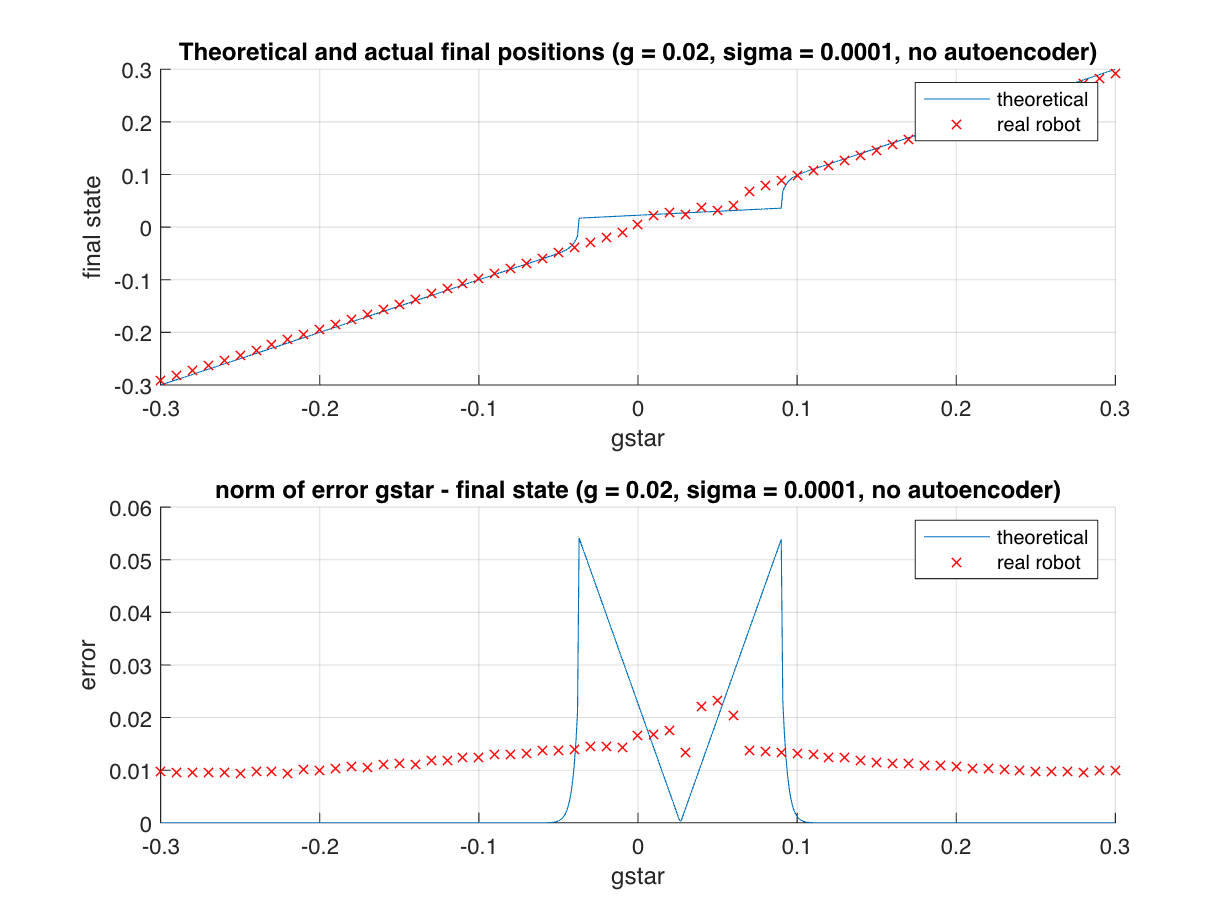

clear
% Theoretical results to replicate on real robot
grange = -0.3:0.001:0.3;
n_steps = 100000;
s = [0;0;0];
emps_s = zeros(length(grange),3);
cals_s = zeros(length(grange),3);
g = [0.5; 0.02665257; 0.25038403];
gstar = g;
sigma_h = eye(3) * .0001;
sigma_d = eye(3) * .0001;
row = 1;
max_alpha = 0.85;
e_alphas = zeros(length(grange),1);
for i = 1:length(grange)
    gstar(2) = grange(i);
    a_h = mvnrnd((gstar-s),sigma_h, n_steps);
    a_r = mvnrnd((g-s),sigma_d,n_steps);
    alpha =  mvnpdf(a_h,(g-s)',sigma_d);
    alpha = min(alpha, max_alpha);
    exp_ar = g - s;
    exp_ah = gstar - s;
    exp_alpha = 1 / ( ((2*pi)^1.5) *sqrt(det(sigma_d + sigma_h)));
    exp_alpha = exp_alpha * exp(-0.5 * (gstar - g)' * inv(sigma_h + sigma_d) * (gstar - g));
%     exp_alpha = min(exp_alpha, 1);
    exp_alpha_ah = 1 / ( ((2*pi)^1.5) *sqrt(det(sigma_d + sigma_h)));
    exp_alpha_ah = exp_alpha_ah * (inv(sigma_h+sigma_d)*(sigma_d*(gstar-s) + sigma_h*(g-s)));
    exp_alpha_ah = exp_alpha_ah * exp(- 0.5 * (gstar - g)' * inv(sigma_h + sigma_d) * (gstar - g));
    if exp_alpha > max_alpha
        exp_alpha = max_alpha;
        exp_alpha_ah = exp_alpha * exp_ah;
    end
    a = exp_ah - exp_alpha_ah + exp_alpha*exp_ar;
    sdot = ((1-alpha).*a_h + alpha.*a_r);
    emps_s(row,:) = mean(sdot)';
    cals_s(row,:) = a;
    e_alphas(row) = exp_alpha;
    row = row + 1;
end

gstar = [repmat(0.5,length(cals_s),1), grange', repmat(0.25038403, length(cals_s),1)];
% Data from real robot
robot_range = -0.3:0.01:0.3;
%novae
final_state_novae = [-0.29149797118334897, -0.28178255034440014, -0.2722625911818634, -0.2622125916816116, -0.25310705585207904, -0.2433111082732547, -0.23371941608068, -0.22380445854179495, -0.21436729558204068, -0.2047453473733111, -0.19510525336874027, -0.1852492473741503, -0.1753876200608724, -0.1660646121238508, -0.15645884195013784, -0.14655147474483857, -0.13696467884233246, -0.12698759366883344, -0.11746533996128679, -0.10785736931063925, -0.09801399752664663, -0.08818882891021099, -0.07833203232240914, -0.06897226090141177, -0.05899107181228661, -0.04900636000218915, -0.03904737175484632, -0.02925668775724699, -0.0197449565110556, -0.009725310445919694, 0.005553940329616319, 0.021971827192302014, 0.02738414912005785, 0.023522859493011503, 0.0377374608526117, 0.03208428495192844, 0.041215053678255766, 0.06855018346543548, 0.07844293129311981, 0.08864071215449183, 0.09833964327343533, 0.10791939346691345, 0.11754606215903043, 0.12711428946317688, 0.13662374538109506, 0.14635447454329084, 0.15616355144481195, 0.16610588930861797, 0.1758252626614888, 0.18554845646716567, 0.19488922926193314, 0.2045543661078161, 0.21409793082150244, 0.22412032392773268, 0.2337799558003808, 0.2433821398711174, 0.2530292856312223, 0.26254426295440564, 0.2723456118650278, 0.2818760055566768, 0.29156020751322964];
dists_novae = [0.009706673917670897, 0.009546248440190053, 0.00957346491167008, 0.00962520779801118, 0.009579501631795845, 0.009322873793573076, 0.00966922580885455, 0.009713728386289549, 0.009446965588489302, 0.010102317448805657, 0.010005088108078979, 0.010276022380861213, 0.010671426900300363, 0.010506726897447262, 0.010991961107560016, 0.01125455593036302, 0.011155312903351684, 0.011814650064775101, 0.011911250956658178, 0.012342503811386383, 0.012439813448039573, 0.012934360711774213, 0.01294128739139625, 0.013109186960963578, 0.013669612629745363, 0.013796875327314703, 0.013997553647618864, 0.014444519892356036, 0.01442603725103821, 0.014380952902053261, 0.016595358670813964, 0.016792792156364086, 0.01752415376622026, 0.013392173864254762, 0.022197656268470776, 0.023211247214463552, 0.02039233388771202, 0.01371950756977474, 0.01364129793572094, 0.013370009623720456, 0.0131711366573547, 0.01295269893192904, 0.012323268528101021, 0.012362022989458129, 0.011849555251862725, 0.011525476664629686, 0.011216378112674593, 0.01134046774724227, 0.010878140970455369, 0.010855152916066849, 0.010682154536285477, 0.010413581102008237, 0.010313888436787419, 0.010040070651178791, 0.009880264971006025, 0.00983610211425823, 0.00983656119505358, 0.009798913452942619, 0.009606444810178633, 0.009855942069751565, 0.009845107467702872];
%vae
final_state_vae = [-0.2918806779573161, -0.2817486331944359, -0.27218145358435636, -0.26218319202732426, -0.25340477798985017, -0.24318835004971998, -0.2337380030732546, -0.22384018707733727, -0.21421120603449145, -0.20474602366080155, -0.19522670122546712, -0.18531165704130442, -0.1754440783552133, -0.16604056574241785, -0.15631731892867481, -0.1466256195906453, -0.13686035236380578, -0.12702360717479055, -0.11761838810192411, -0.10787836512624745, -0.0980179774281353, -0.08828837405574998, -0.07840133893513342, -0.06893449554409044, -0.05902334911130265, -0.049164663186860504, -0.03906248078805659, -0.02929337589713051, -0.019753254994574018, -0.00968465106723308, 0.020733866861341856, 0.036253974715542966, 0.041583131777442064, 0.04895508707336636, 0.04879735134090386, 0.053396264191467945, 0.05976882979819602, 0.06914318186500527, 0.07861855724277476, 0.0886898950799524, 0.09838331181711639, 0.10799053582246818, 0.11758643069997085, 0.12717794430927123, 0.13676400532384808, 0.14644933182130654, 0.15617588029613455, 0.1662544042724986, 0.17579633977452241, 0.1857168883126472, 0.19488539535363056, 0.20452598850203524, 0.21420948034785678, 0.22411566678578745, 0.23361096497251527, 0.24345597718316148, 0.2530822445912305, 0.26254107683033673, 0.2722339330021003, 0.2819784300310391, 0.29148325670494624];
dists_vae = [0.009260736431369898, 0.009585188293867113,0.00967386629955955, 0.009691342612035279, 0.009247293039052598, 0.009468818399680383, 0.009655386682427703, 0.009668579561737693, 0.009640383237884935, 0.010082853018299635, 0.009846352210356582, 0.010189337471613862, 0.010534506623464215, 0.010558288043439576, 0.01104914777015812, 0.011341895755077647, 0.011250198018137017, 0.011768046724965809, 0.011964353528012199, 0.01236530893040837, 0.01280169327389943, 0.01285322742740672, 0.01289584671097727, 0.013260236427727418, 0.013307704087816256, 0.013711422090493275, 0.014175219163260326, 0.014371241949669425, 0.014388729968066945, 0.014442423050948068, 0.020816802217014815, 0.026905786709920644, 0.021842567794852434, 0.01907098401854043, 0.01012436875353897, 0.01192917516084575, 0.014034558193186272, 0.013675510048597881, 0.013601855503634155, 0.013664467320989946, 0.012951881342722255, 0.012974958154400763, 0.012479507513310593, 0.012235008801061355, 0.011808106427852252, 0.011421835516680785, 0.011268770868114206, 0.01111523808037603, 0.011013611985476644, 0.010625354191983452, 0.010529727952287501, 0.0104583800728755, 0.010265553371502445, 0.00997423290170519, 0.010012647411339051, 0.009829677735332646, 0.009737112519883037, 0.009820287795145752, 0.00978347995386697, 0.00977261410039723, 0.009922972609373698];
figure
subplot(2,1,1)
hold on
grid on
plot(grange, cals_s(:,2))
plot(robot_range, final_state_novae, 'rx')
legend('theoretical','real robot')
xlabel('gstar')
ylabel('final state')
title('Theoretical and actual final positions (g = 0.02, sigma = 0.0001, no autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(grange, vecnorm(gstar - cals_s,2,2))
plot(robot_range, dists_novae, 'rx')
legend('theoretical','real robot')
xlabel('gstar')
ylabel('error')
title('norm of error gstar - final state (g = 0.02, sigma = 0.0001, no autoencoder)')

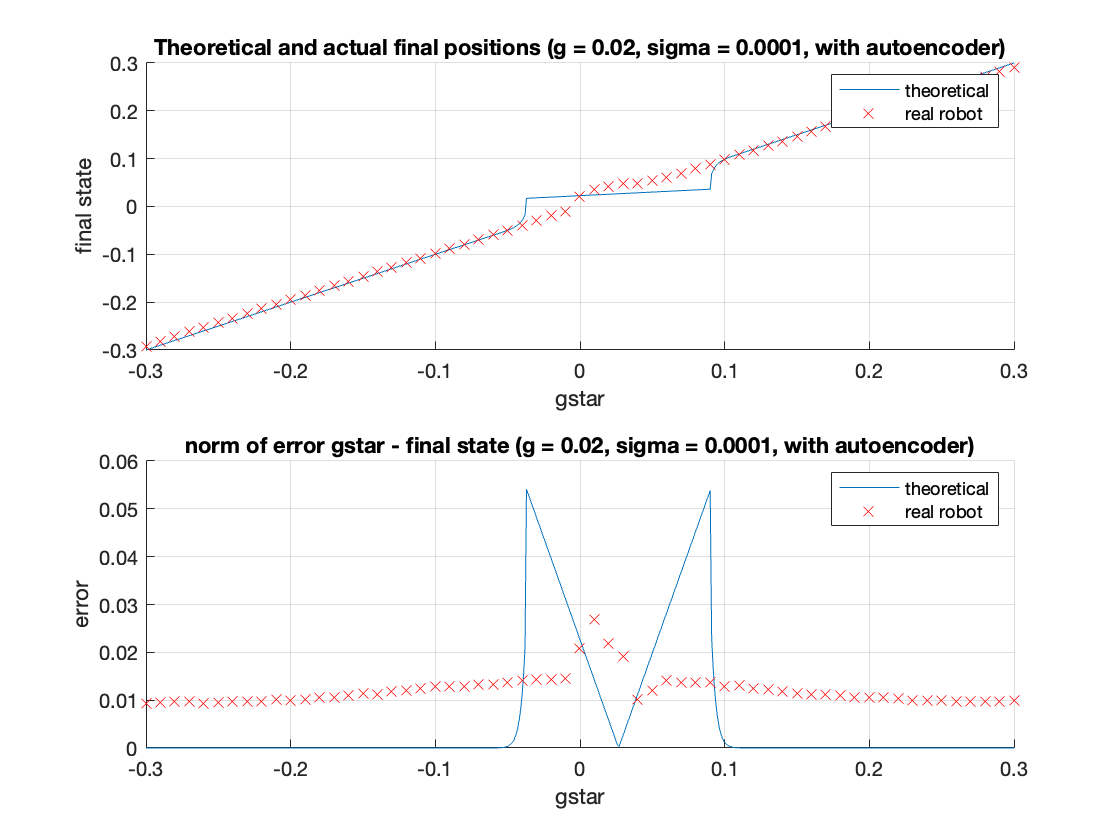

figure
subplot(2,1,1)
hold on
grid on
plot(grange, cals_s(:,2))
plot(robot_range, final_state_vae, 'rx')
legend('theoretical','real robot')
xlabel('gstar')
ylabel('final state')
title('Theoretical and actual final positions (g = 0.02, sigma = 0.0001, with autoencoder)')
subplot(2,1,2)
hold on
grid on
plot(grange, vecnorm(gstar - cals_s,2,2))
plot(robot_range, dists_vae, 'rx')
legend('theoretical','real robot')
xlabel('gstar')
ylabel('error')
title('norm of error gstar - final state (g = 0.02, sigma = 0.0001, with autoencoder)')

% Some previously used final states
% final_state =  [-0.29598721237788167, -0.2859176756977869, -0.2760991320765544, -0.26622981851104954, -0.256463952919082, -0.2462954581462106, -0.2366068026415427, -0.22653152238589475, -0.21664867803026358, -0.20710054379644136, -0.19740681325439985, -0.18727705246853338, -0.17766537877389726, -0.1677752466811549, -0.15828081889380172, -0.14828663559186425, -0.13837577208555457, -0.12842848123583012, -0.11859326389077288, -0.10864972522003824, -0.09880112676076039, -0.08892527080108666, -0.07905786291060568, -0.06939226706357898, -0.05937949747924948, -0.04912902409504796, -0.03911312338245052, -0.029372156332834676, -0.008525061319432228, 0.021321104564085418, 0.02416498697495346, 0.02048381623895382, 0.027383751767875747, 0.028699099056069287, 0.03228117463380571, 0.0417554622893347, 0.05556510343529466, 0.06666283585479581, 0.0778085141367317, 0.08888251183885808, 0.09899218835946337, 0.1088524174233874, 0.11866998578014501, 0.1282683994297341, 0.1379145121967666, 0.14804915001386057, 0.15794036757313692, 0.16792159857839467, 0.17774453274092702, 0.18770681968265773, 0.1974632908534786, 0.20689072297273992, 0.21715842321638826, 0.22709129121380486, 0.23683522715689467, 0.24636130005603712, 0.25609145460829896, 0.26630823030288825, 0.2761575675454217, 0.28594785700291403];
% final_state = [-0.09857801355261622, -0.08877780219897309, -0.07911187391819315, -0.06952261455929194, -0.06041581557891406, -0.05279273001536135, -0.047158050940070737, -0.042445402123672836, -0.03741906386141822, -0.031881752828529314, 0.054322358451334186, 0.060838016568165426, 0.06698936857328178, 0.07245390223962966, 0.07755745453291338, 0.08271447166249743, 0.08654337703901238, 0.08961103987106704, 0.09211071021671743, 0.094567034284994];
% final_state = [-0.292298075464149, -0.28181786843310574, -0.2724261648031622, -0.26250325502696553, -0.2533227537581397, -0.24353995400959438, -0.23401440751139707, -0.22446520660031077, -0.21452622439928687, -0.20494447886981734, -0.19550496718985905, -0.18543615066932115, -0.17612130025597617, -0.16653351943979175, -0.15661209417274843, -0.14688500055392734, -0.1372753743886258, -0.1273745020188556, -0.1179218689058711, -0.10815611074945121, -0.0986515199250073, -0.08861672220554517, -0.07895019723628705, -0.06958352337438262, -0.060675587838074196, -0.052763726244213126, -0.04715418851250738, -0.042340115120578316, -0.03757377062504835, -0.031875590592294854, 0.054629930995900564, 0.06085929133115337, 0.06703185718026493, 0.07261091563459729, 0.07758929394877448, 0.08262946882533671, 0.08649453755036528, 0.0896190792703539, 0.09209553847435266, 0.09454211108624726, 0.09984223262509567, 0.10849191316632537, 0.11782099901025725, 0.12732468795072904, 0.1367876638978336, 0.14656317191468676, 0.15617866684993642, 0.1663694899038305, 0.17577811869900395, 0.18564631619077557, 0.19489164201364262, 0.20457160335071045, 0.2142975204387166, 0.22412224010223128, 0.23368592422536183, 0.24350781473645167, 0.2528639083136256, 0.262510623960026, 0.2723016990161896, 0.28204414380237075];
% final_state = [-0.3290304161027411, -0.3134754233999539, -0.3040444744115347, -0.29370237570537877, -0.2821453497434455, -0.2774916135001626, -0.2716525483261393, -0.2667063281979052, -0.2617464941158271, -0.2566559020942199, -0.2514143277991209, -0.24658225320923735, -0.24207846278764497, -0.23730314317762335, -0.2316156815630562, -0.22233470282794335, -0.21496024731369276, -0.19650566003130227, -0.18347236795641403, -0.17303361544307042, -0.1635740413537075, -0.1547367375697994, -0.14548927004038012, -0.13541690877449056, -0.11952221642908308, -0.11046985037566719, -0.09456217739931301, -0.09322924239095076, -0.08142208673350455, -0.0688883875739287, 0.015957779535566957, 0.07015186196906173, 0.07787798645416219, 0.08612084872334189, 0.09458914484008672, 0.10263463317476285, 0.11047427072287123, 0.12256312841834352, 0.13033318228642382, 0.13555839719128646, 0.14131258348910064, 0.14873725530427703, 0.1563225254146672, 0.16228473128057982, 0.16870666053401223, 0.18931230685547368, 0.18811624402798816, 0.1867519395952582, 0.18779325234362226, 0.19222682404956554, 0.19951907860674695, 0.2074779825190057, 0.21647544722659617, 0.22537938276964603, 0.2347601524157843, 0.24447863612055495, 0.2535246805161563, 0.2631057912771516, 0.2727383459027334, 0.28264229854967077];
% final_state = [-0.29149560204901215, -0.28156381771897776, -0.2721904251443619, -0.26225882022069236, -0.25312746713774115, -0.24323910573098698, -0.23382154772230254, -0.22371600356276788, -0.2143629889247202, -0.20459170957983366, -0.1949332356829398, -0.18501458429320222, -0.1753483387919661, -0.16564281073047618, -0.15601422876121346, -0.1462099476091128, -0.13643911585446236, -0.1265499895837458, -0.11699887720078968, -0.10683553852933418, -0.0963502121443662, -0.08572180228494294, -0.07362507307485677, -0.059689212507129816, -0.027951035603891682, -0.0033308109601641656, -0.0010548814183937445, 0.022638489404688173, 0.0020272640468594026, 0.019612268977821784, 0.032376598028715266, 0.027902890794485758, 0.032397407414808385, 0.029385296442679953, 0.018092743937891613, 0.034755910512222606, 0.040585766211352445, 0.05155772752317441, 0.058884593701532505, 0.07822181797846843, 0.08879429279459612, 0.10283033658886827, 0.116862243861754, 0.12691464231752908, 0.13655832519318556, 0.14639019187844263, 0.15607997136595197, 0.16614294846017574, 0.17558516647941727, 0.18550917050916974, 0.1946313607344084, 0.20434764885218398, 0.21396289554733133, 0.22344608362847435, 0.233297233391553, 0.24314222943605004, 0.2526830958366435, 0.26232119874392174, 0.27195867671263807, 0.28157752050088214];
% final_state = [-0.32934123085831696, -0.3145720907597405, -0.2991161261831479, -0.29136803636646996, -0.2819219033538247, -0.2773167687695482, -0.2714351897139698, -0.2662693328578322, -0.26127209898600345, -0.2564906952322107, -0.25137837315084854, -0.2462947344014926, -0.24182553424893438, -0.23701861257323578, -0.23149840360523188, -0.2227234961753572, -0.2147854721768289, -0.20222358774064558, -0.18356625773692067, -0.17201240034846274, -0.16325380353129518, -0.1536018885425005, -0.14526335980717864, -0.1354334019830029, -0.12092731449186533, -0.11110921767719732, -0.0956162442998336, -0.08953097547832498, -0.08054697687641103, -0.06811362691740681, 0.018739603201562788, 0.07084003644855418, 0.07878792905798289, 0.08661466023600844, 0.09517487105295494, 0.10350243357257152, 0.11283809804178555, 0.12316790662688466, 0.13059645892395574, 0.1358846240137054, 0.14204003473077229, 0.14903110621221347, 0.15651236014223016, 0.16364811436399168, 0.16872139622894003, 0.18025054652780312, 0.1902949397427625, 0.18982393616974796, 0.1897226945552346, 0.19273194126402532, 0.19981683269783979, 0.20787324954471806, 0.21656386396744823, 0.22564144925309765, 0.23503822189749196, 0.24442448050026075, 0.2536647253085625, 0.26306277408115825, 0.27271635409897377, 0.2825291785188483];
% final_state = [-0.09804772996391604, -0.08816034245808345, -0.07828388661820684, -0.06884403221674043, -0.05894003584346996, -0.049055927851058674, -0.03911429766117247, -0.029289197523118, -0.019745315979649108, -0.009750008356038658, 0.00803939287207614, 0.02211340505766314, 0.02774497675278607, 0.022923689809626994, 0.030576520607905416, 0.03219117702648479, 0.03475277893631824, 0.06850138597710208, 0.07842175896833153, 0.08852998009227105];


% % multivariate case
% n_steps = 100000;
% gstar = [0.64743481; 0.02665257];
% sigma_h = eye(2) * 0.001;
% sigma_d = eye(2) * 0.001;
% s = [0;0];
% % g_breadth = 20;
% emps_s = zeros(40,40,2);
% cals_s = zeros(40,40,2);
% % pos = 1;
% G = zeros(40,40,2);
% g = [0;0];
% row = 1;
% col = 1;
% for i = 0:0.05:2
%     for j = 0:0.05:2
%         g(1) = i;
%         g(2) = j;
%         a_h = mvnrnd((gstar-s),sigma_h, n_steps);
%         a_r = mvnrnd((g-s),sigma_d,n_steps);
%         alpha =  mvnpdf(a_h,(g-s)',sigma_d);
%         exp_ar = g - s;
%         exp_ah = gstar - s;
%         exp_alpha = 1 / (2*pi*sqrt(det(sigma_d + sigma_h)));
%         exp_alpha = exp_alpha * exp(-0.5 * (gstar - g)' * inv(sigma_h + sigma_d) * (gstar - g));
%        
%         exp_alpha_ah = 1 / (2*pi*sqrt(det(sigma_d + sigma_h)));
%         exp_alpha_ah = exp_alpha_ah * (inv(sigma_h+sigma_d)*(sigma_d*(gstar-s) + sigma_h*(g-s)));
%         exp_alpha_ah = exp_alpha_ah * exp(- 0.5 * (gstar - g)' * inv(sigma_h + sigma_d) * (gstar - g));
%         a = exp_ah - exp_alpha_ah + exp_alpha*exp_ar;
%         sdot = ((1-alpha).*a_h + alpha.*a_r);
%         emps_s(row,col,:) = mean(sdot)';
%         cals_s(row,col,:) = a;
%         G(row,col,:) = g;
%         col = col + 1;
%     end
%     row = row + 1;
%     col = 1;
% end
% 
% figure
% surf(0:0.05:2,0:0.05:2,emps_s(:,:,2))
% figure
% surf(0:0.05:2,0:0.05:2,cals_s(:,:,2))
% norm_dist = zeros(41,41);
% for i=1:41
%     for j=1:41
%         norm_dist(i,j) = norm([cals_s(i,j,1),cals_s(i,j,2)]);
%     end
% end
% surf(0:0.05:2,0:0.05:2,norm_dist)